# **Adaptive and Cooperative Adaptive Cruise Control**

Brian Lesko

Masters of Mechanical Engineering

Ohio State University

February 28, 2023

`Originaly a Simulink & Matlab Markdown file`

`By Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc`

# `Contents `

`1. Introduction `

`2. Recent papers`

`3. String Stability`

`4. Longitudinal Model`

`5. Time Gap and Standstill Distance`

`6. Adaptive cruise control`

`7. Cooperative adaptive cruise control`

`    i) Identical Vehicle Sim`

`    ii) Varying Vehicle Sim`

`8. String Stability Evaluation`

# Introduction

    Cooperative adaptive cruise control (CACC) is an extension of adaptive cruise control (ACC) that uses vehicle-to-vehicle (V2V) communication to enable cooperative maneuvers by connected and automated vehicles (CAVs). CACC can improve road safety, traffic efficiency and fuel economy by reducing inter-vehicle gaps and human errors. Several recent papers have addressed various challenges related to CACC design and implementation with one key aspect being stability of vehicle platoons, known as string stability.

# Recent Papers

    Published in 2019 Columbia university investigated string stability and fuel efficiency for a vehicle platoon with different types of vehicles and communication delays.1 Published in 2018 Cornell University proposed a reinforcement learning approach for cooperative adaptive cruise control (CACC) that can learn a robust communication protocol and coordination policy without requiring full communication among vehicles. The paper shows that the proposed method can achieve string stability and fuel efficiency under various communication scenarios. 2 Published in 2016, Princeton University developed an artificial potential field approach for CACC. The paper proposes this method because it can achieve both gap closing and collision avoidance using a nonlinear controller that combines artificial potential field approach with model predictive control. This method can also accomplish both path planning and motion control synchronously. 3 A paper published in 2020 by researchers from Cornell University and Ford Motor Company proposes a data-driven approach for vehicle dynamics modeling using neural networks that can capture nonlinearities and uncertainties. this paper presents a data-driven approach for vehicle dynamics modeling using neural networks that can capture nonlinearities and uncertainties. The paper uses a deep neural network with an interpretable Koopman operator to represent the nonlinear dynamics in a linear lifted feature space1. The paper also compares the proposed approach with model predictive control algorithms using a nonlinear model and a linear time-varying model, and shows that the proposed approach has better tracking accuracy and higher computational efficiency. The paper also demonstrates the applicability of the proposed approach for preview control in autonomous vehicles. 4

[1)](https://ieeexplore.ieee.org/document/8320840) Z. Wang, Y. Zhang and J. Wang, “Adaptive Optimal Control of Heterogeneous CACC System With Uncertain Parameters,” in IEEE Transactions on Intelligent Transportation Systems, vol. 19, no. 8, pp. 2696-2707, Aug. 2018.

[2)](https://wensun.github.io/CS4789.html) W. Sun, A. Nedic and U. Topcu, “Reinforcement Learning for Cooperative Adaptive Cruise Control,” 2018 IEEE Conference on Decision and Control (CDC), Miami Beach, FL, USA, 2018, pp. 6494-6501.

[3)](https://ieeexplore.ieee.org/document/7535411) Semsar-Kazerooni, E., Verhaegh, N., & Keviczky, T. (2016). Cooperative adaptive cruise control: An artificial potential field approach. In 2016 IEEE Intelligent Vehicles Symposium (IV) (pp. 1009-1014). IEEE.

[4)](https://arxiv.org/abs/2007.02219) Deep Neural Networks with Koopman Operators for Modeling Vehicle Dynamics. Zhenyu Zhang, Yiqi Gao, and Hui Peng. [arXiv preprint arXiv:2007.02219 (2020).](https://arxiv.org/abs/2007.02219)

# String Stability

    String stability and other evaluation methods for vehicle platoons have gained significant attention in recent years as advancements in cooperative adaptive cruise control (CACC) and vehicle autonomy continue to develop. String stability is a vital aspect of CACC systems, as it ensures that disturbances in the platoon, such as sudden braking or acceleration, do not amplify as they propagate through the vehicles in the platoon. Evaluation methods for vehicle platoons encompass various aspects, such as fuel efficiency, communication protocols, and collision avoidance. By investigating these methods, researchers aim to improve the safety, efficiency, and overall performance of autonomous vehicle platoons.

    Evaluating string stability through a known plant model involves analyzing the transfer functions of vehicles within a platoon. Transfer functions mathematically represent the relationship between the input and output of a linear, time-invariant system. In the context of vehicle platooning, these transfer functions model how disturbances in one vehicle propagate to the others in the platoon. By analyzing the frequency domain characteristics, such as gain and phase margins, of the overall platoon transfer function, researchers can determine whether the platoon exhibits string stability. If the platoon system's transfer function demonstrates sufficient stability margins, it indicates that the platoon can effectively dampen disturbances, ensuring safe and efficient operation.

# 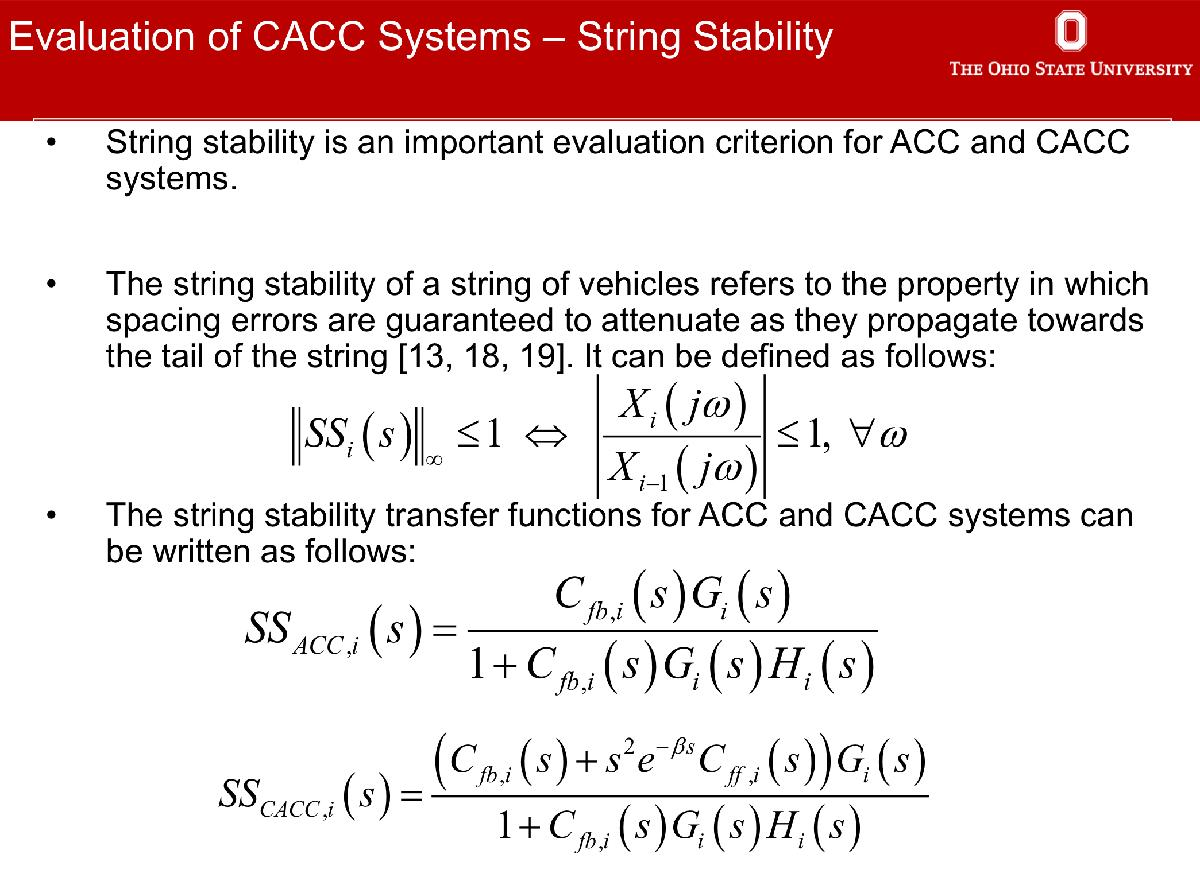

String Stability using transfer functions

# Longitudinal Model

clc; clear; close all;

**Vehicle Transfer Functions: Position, Speed, Acceleration with input as motor torque**

    A vehicle's time constant can be taken from 0.3<T<0.7. This time constant represents how fast the vehicle can respond to a change in the input, which is often taken as motor torque. This simplified model is validated from longitudinal dynamics simulations in BrianLesko/VehicleSystems/Modeling/LongitudinalDynamics

s = tf('s'); K = 1; T = 0.3;

%The Vehicle Position Transfer function
Gp = K / (s * (T*s + 1)); %Position transfer function

%Vehicle Speed Transfer Function
Gv = K/(T*s+1);

%Vehicle Acceleration Transfer Function
Ga = K*s/(T*s+1);

# Time Gap and Standstill distance

**H, the feedback path function**

- Insures constant vehicle spacing with zero standstill distance, standstill distance can be changed by modifying the input signal

- the gap time, tauh or Thd is a measure of seconds a lag car would travel before hitting a suddenly stopping lead car. It can be different for each vehicle in CACC

- the vehicle lengths will be taken as zero for simplification purposes.

s = tf('s'); tauh = 0.6; 
H = 1+ tauh*s;

*This feedback path cannot be implemented directly because it is impropper. So it must instead be implemented in the following way*

# Automatic Cruise Control, ACC

***5 Vehicle Platoon follwing a 6th vehicle using real highway vehicle data***

***The ACC Simulink  Model***

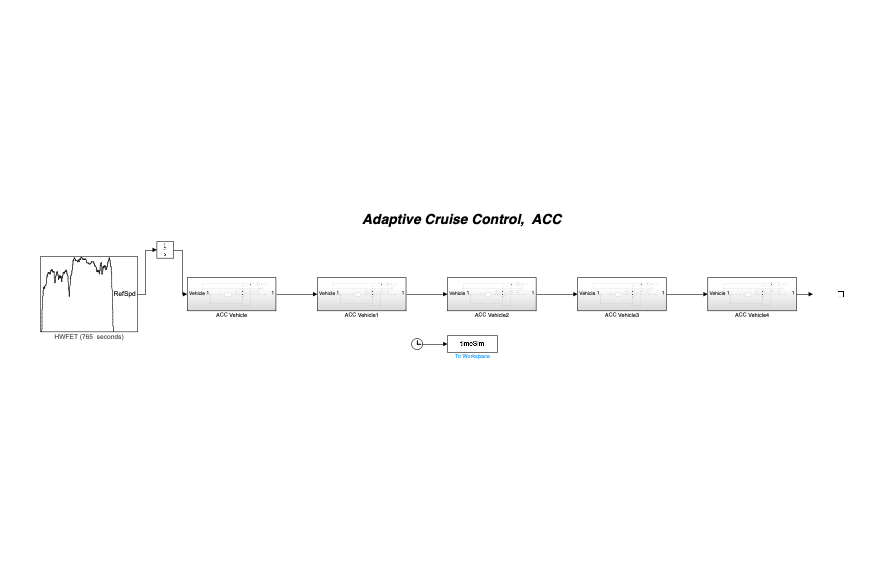

### Each ACC Vehicle Submodel

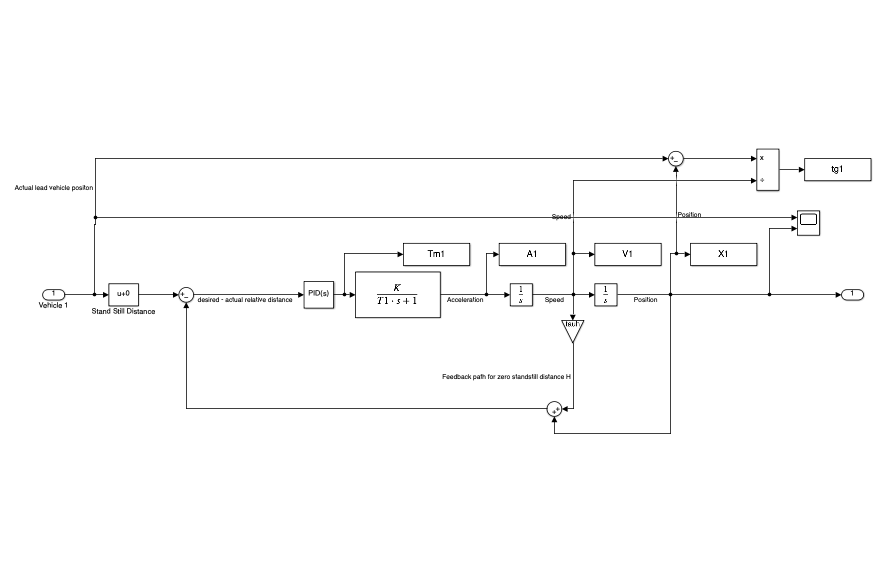

## **5 Identical Vehicles**

## Vehicle Controllers, PID

% lead vehicle 
Kp1 = 1; Ki1 = 0; Kd1 = 3; N1=100;

% proportional gain
Kp2 = Kp1; Kp3 = Kp1; Kp4 = Kp1; Kp5 = Kp1;

% inregral gain
Ki2 = Ki1; Ki3 = Ki1;  Ki4 =  Ki1;  Ki5 =  Ki1;

% derivative gain
Kd2 = Kd1; Kd3 = Kd1;  Kd4 =  Kd1;  Kd5 =  Kd1;

% filtering 
N2 = N1; N3 = N1;  N4 =  N1;  N5 =  N1;

## Linearized Vehicle Models, V/Tm = (K/Ts + 1)

K = 0.6;

% Time Constants 
T1 = 0.6; T2 = T1; T3 = T1; T4 = T1; T5 = T1;

## Simulate Platoon of Automatic Cruise Control

skip this step if a valid csv file exists

sim('ACC_5.slx');
ID = ['ACC_5'];

## Reduce Time samples 

b = round(max(time)*2); % samples per second of sim time
[IDvec,time,vehNum,Tm,X,V,A,tg,timeGap] = ReduceSamplesAndStack(b,time,Tm1,Tm2,Tm3,Tm4,Tm5,X1,X2,X3,X4,X5,V1,V2,V3,V4,V5,A1,A2,A3,A4,A5,tg1,tg2,tg3,tg4,tg5,ID);

## Save data to a table

names = {'IDvec','vehNum','time','Tm','X','V','A','timeGap'};
accSim = table(IDvec,vehNum,time,Tm,X,V,A,timeGap, 'VariableNames', names);
writetable(accSim, 'accSim.csv', 'Delimiter', ',', 'QuoteStrings', true);

## Import the CSV file to a table

skip if you just re-ran the simulink 

% csv -> table

## Plot the ACC data

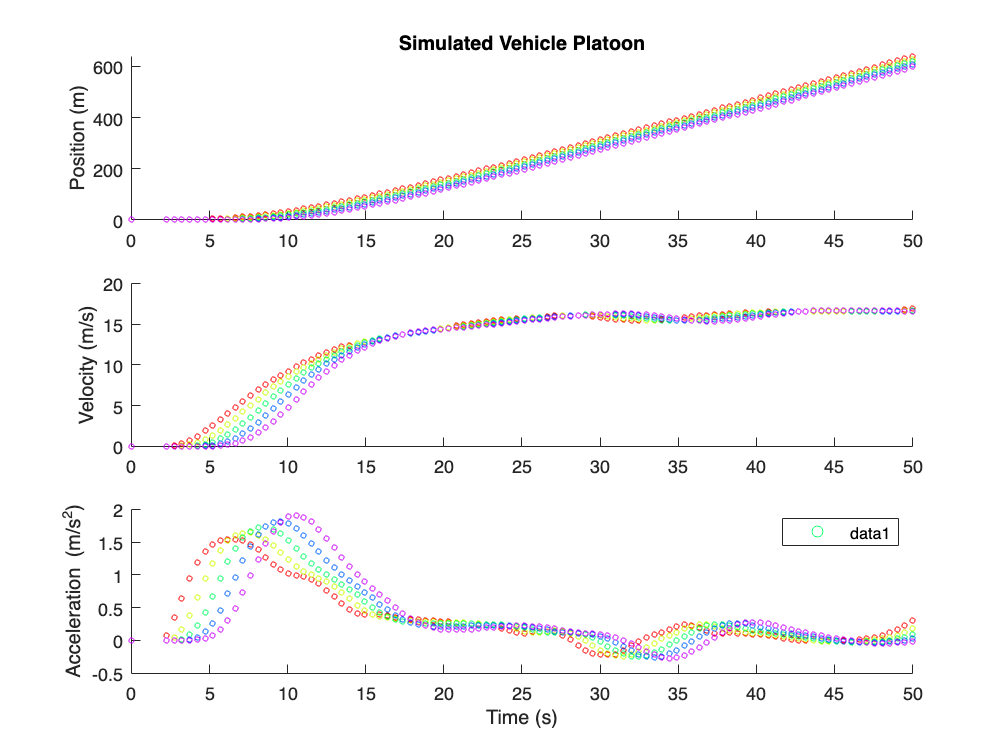

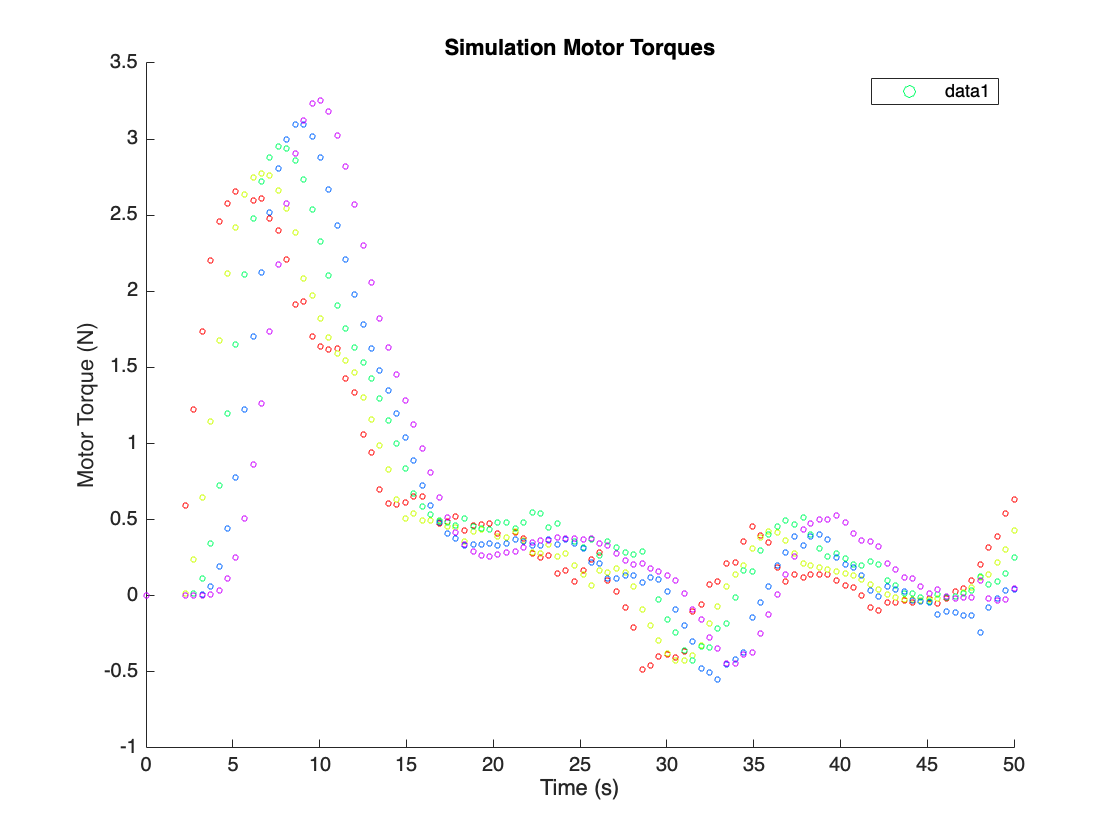

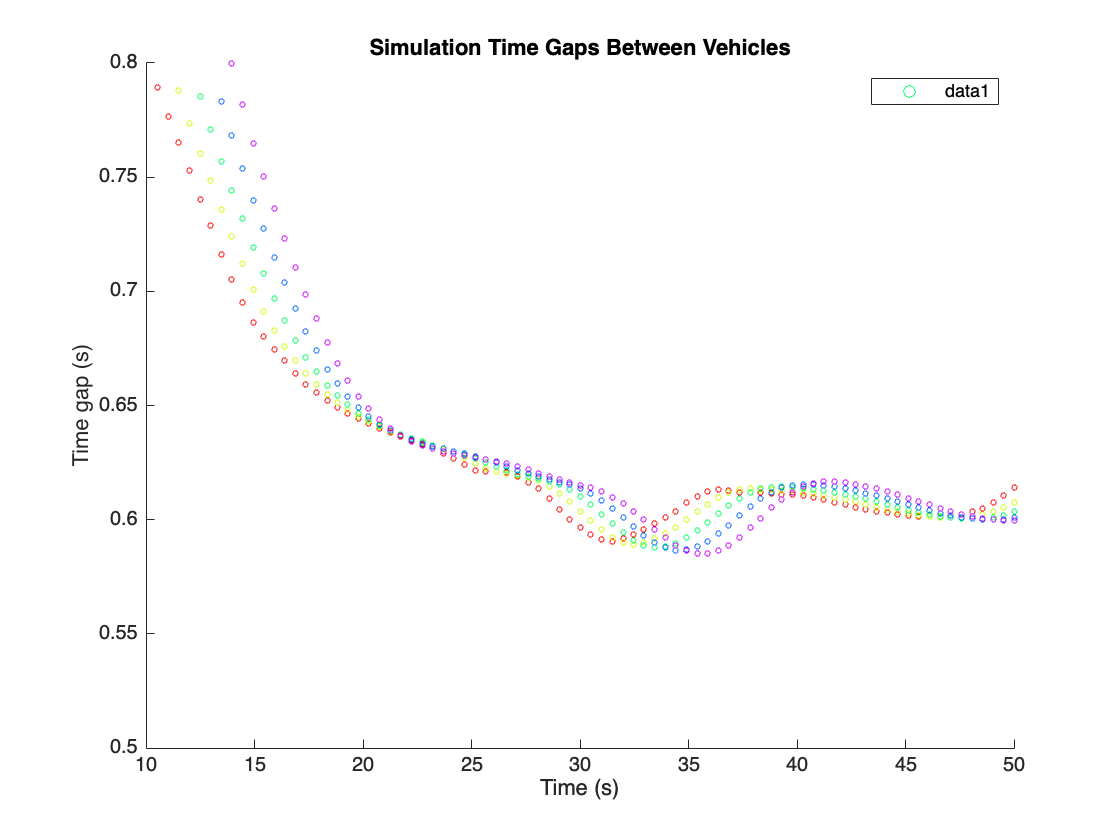

plotSim(accSim)

The acceleration strength and motor torques are limiting factors for comfort, acceleration should be smoothed 

TauH is set as 0.6 and is the goal for the time gap, this platoon is able to keep it fairly well

# **Cooperative Automatic Cruise Control**

## **5 Idential Vehicles Simulation, "Homogeneous Simulation"**

#### **CACC Simulink Model**

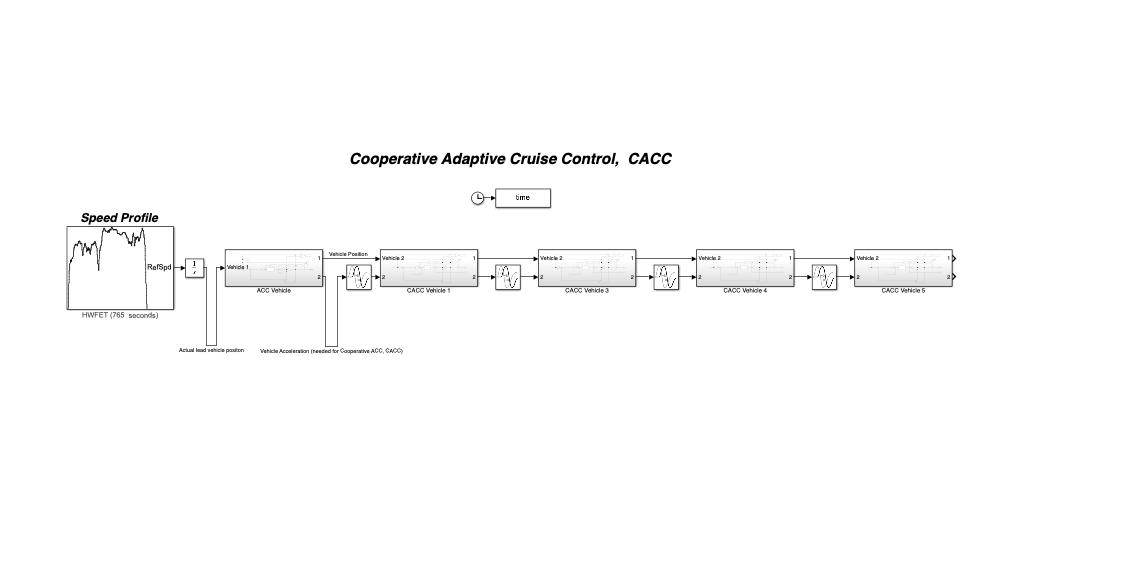

#### Each CACC Vehicle Submodel

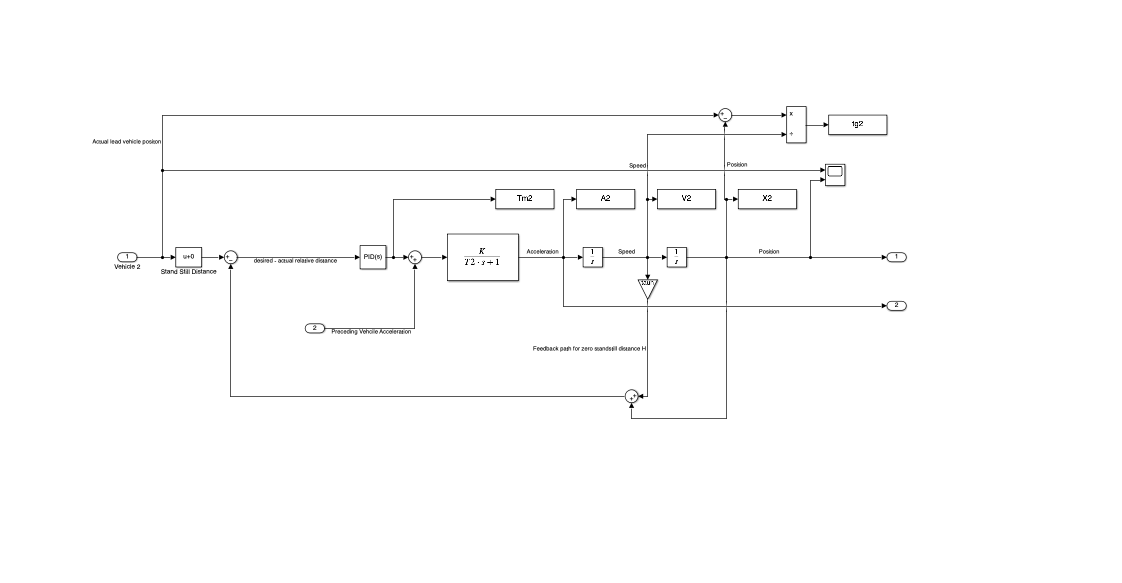

## **Time gap and Time delays**

tauh = 0.6; % time gap
time_delay1 = 0.3; time_delay2 = 0.3; time_delay3 = 0.3; time_delay4 = 0.3; time_delay5 = 0.3; 

## Simulate

skip this step if a valid csv file exists and is imported

sim('CACC_5.slx');
ID = ['CACC_5'];

## Reduce Time samples 

b = round(max(time)*2); % samples per second of sim time
[IDvec,time,vehNum,Tm,X,V,A,tg,timeGap] = ReduceSamplesAndStack(b,time,Tm1,Tm2,Tm3,Tm4,Tm5,X1,X2,X3,X4,X5,V1,V2,V3,V4,V5,A1,A2,A3,A4,A5,tg1,tg2,tg3,tg4,tg5,ID);

## Save data to a table

names = {'IDvec','vehNum','time','Tm','X','V','A','timeGap'};
caccSim = table(IDvec,vehNum,time,Tm,X,V,A,timeGap, 'VariableNames', names);
writetable(caccSim, 'caccSim.csv', 'Delimiter', ',', 'QuoteStrings', true);

## Plot the Homogeneous CACC data

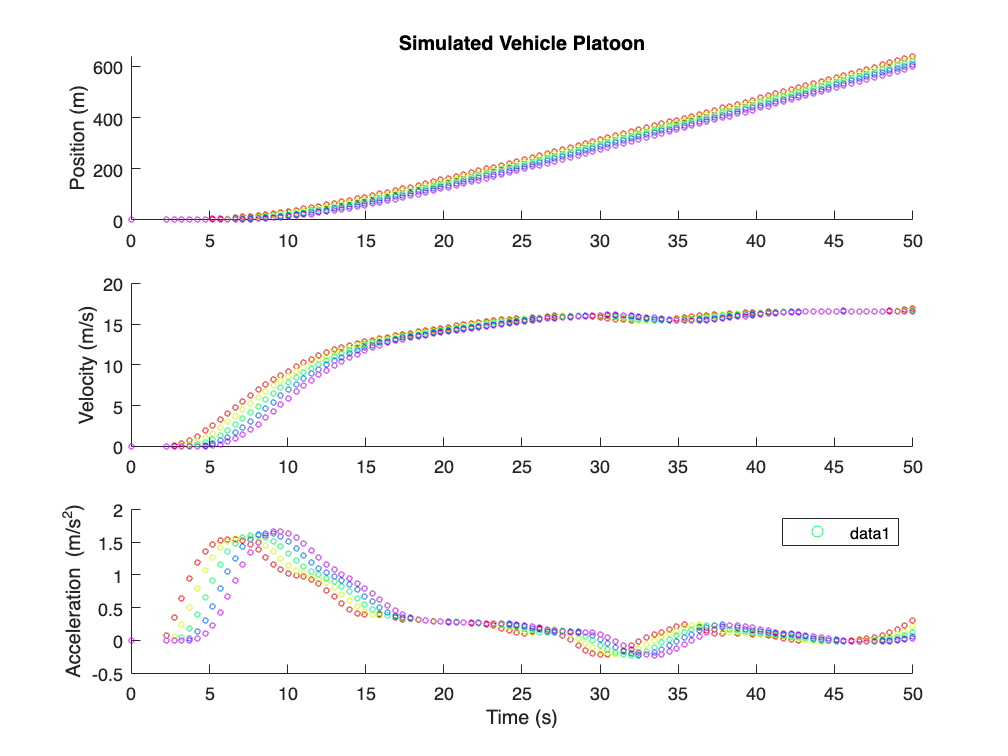

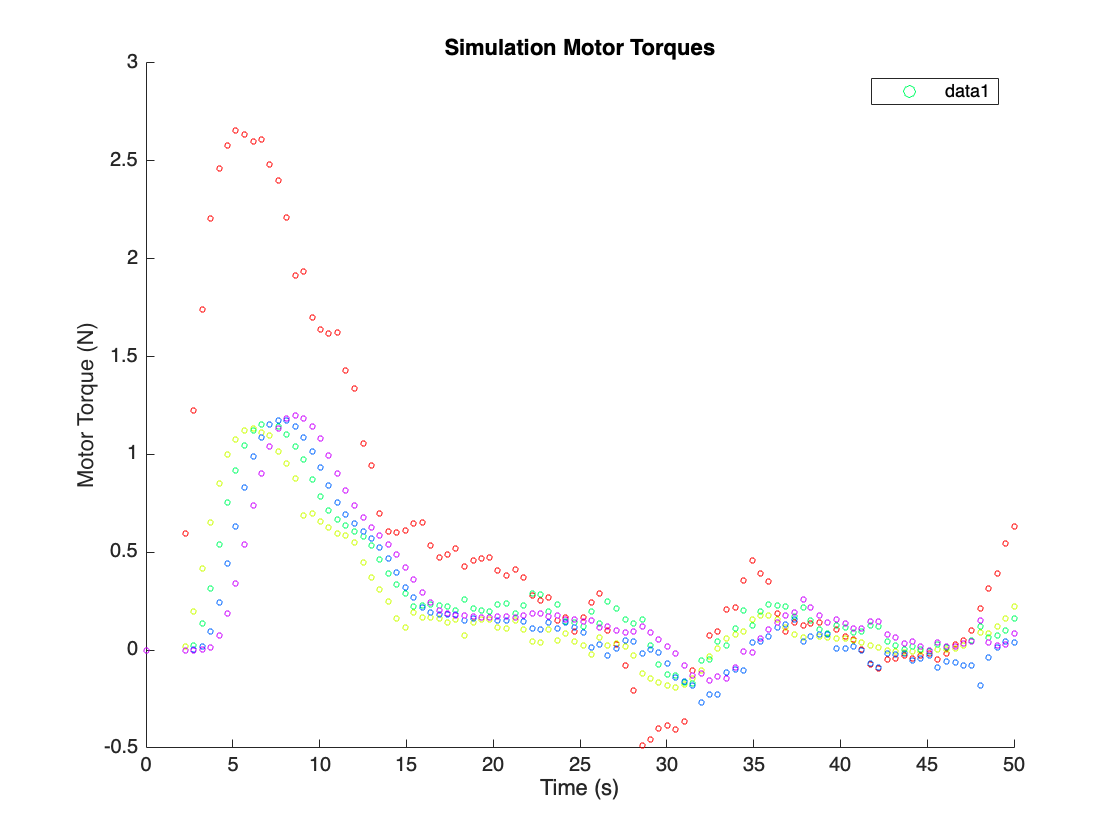

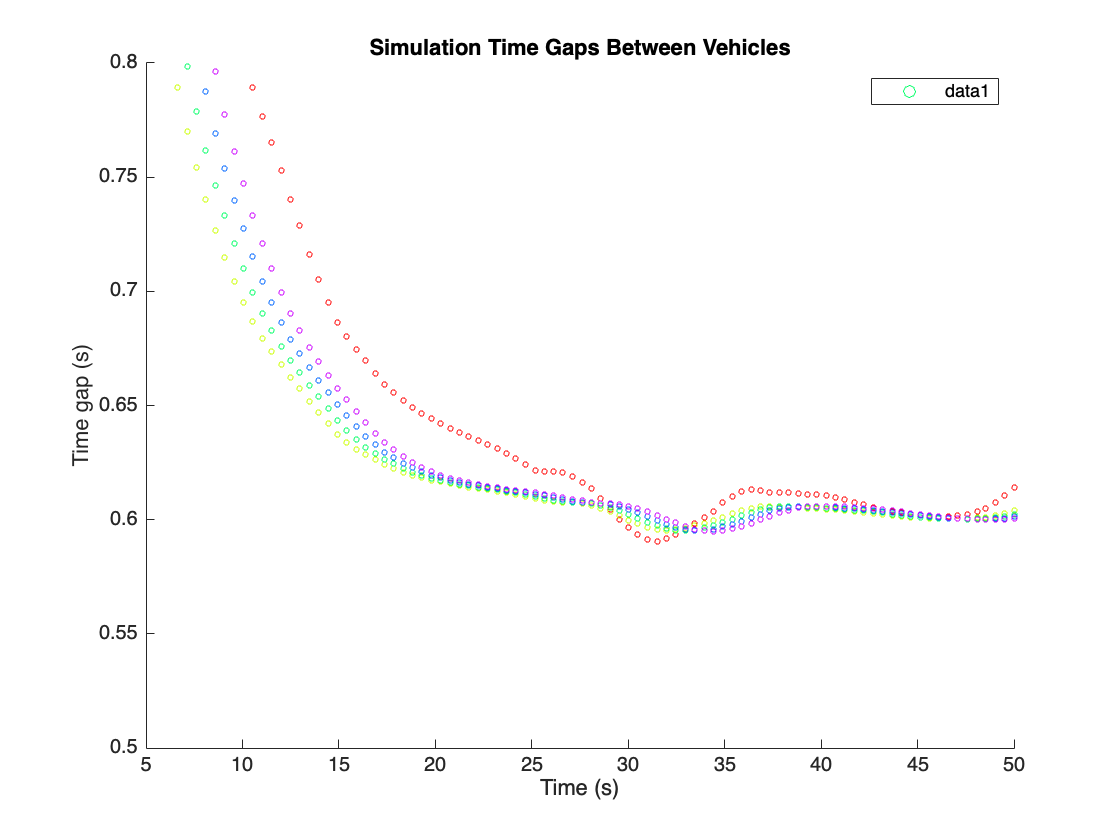

plotSim(caccSim)

The acceleration strength and motor torques are limiting factors for comfort, acceleration should be smoothed 

# **Cooperative Automatic Cruise Control**

## **5 Differing Time Constants Vehicle Simulation, "Heterogeneous"**

**time gap goal **

tauh = 0.6;

**Setting Time delays for acceleration communication**

time_delay1 = 0.3; time_delay2 = 0.4; time_delay3 = 0.6; time_delay4 = 0.35; time_delay5 = 0.7; 

## Simulate

you can skip this step if a valid csv file exists and an import statement exists

sim('CACC_5.slx');

## Reduce Time samples 

b = round(max(time)*2); % samples per second of sim time
[IDvec,time,vehNum,Tm,X,V,A,tg,timeGap] = ReduceSamplesAndStack(b,time,Tm1,Tm2,Tm3,Tm4,Tm5,X1,X2,X3,X4,X5,V1,V2,V3,V4,V5,A1,A2,A3,A4,A5,tg1,tg2,tg3,tg4,tg5,ID);

## Save data to a table

names = {'IDvec','vehNum','time','Tm','X','V','A','timeGap'};
caccSimHeterogeneous = table(IDvec,vehNum,time,Tm,X,V,A,timeGap, 'VariableNames', names);
writetable(caccSimHeterogeneous, 'caccSimHeterogeneous.csv', 'Delimiter', ',', 'QuoteStrings', true);

## Plot the Homogeneous CACC data

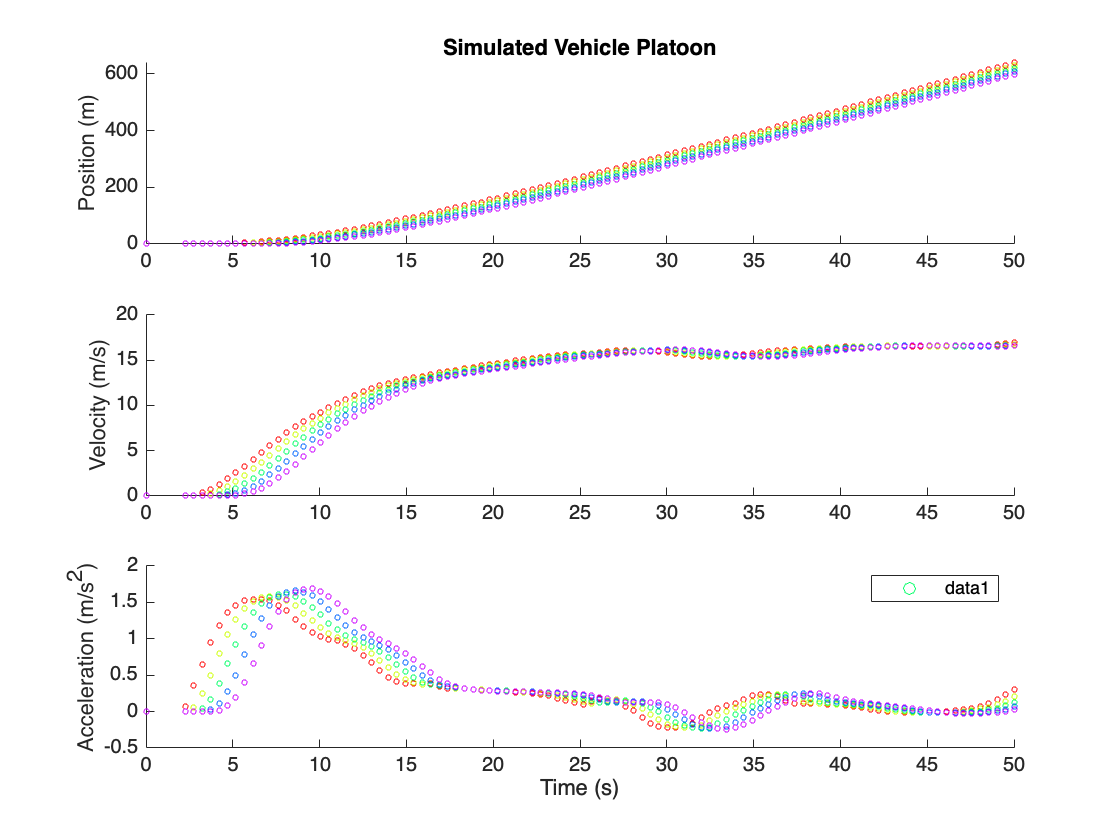

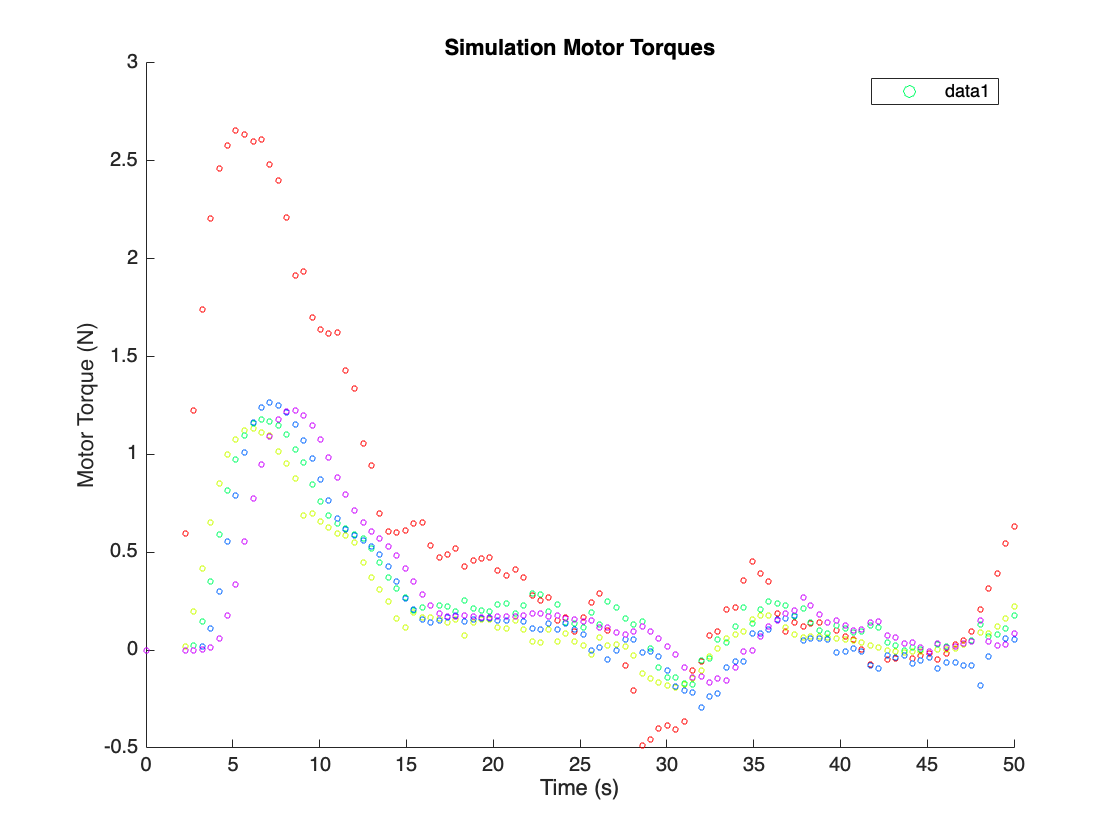

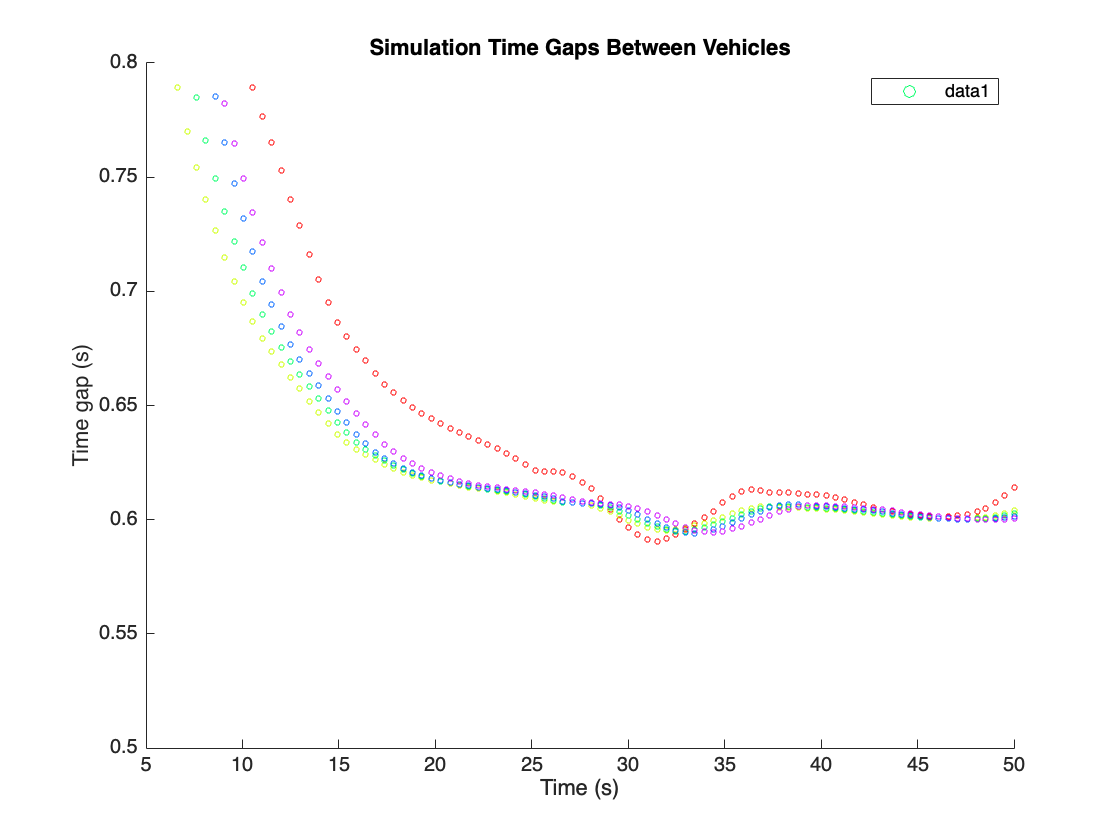

plotSim(caccSimHeterogeneous)

There is no noticable decrease in performance with the heterogeneous simulation compared to the homogeneous simulation

## String Stability Based on the transfer functions 

B = 0; % for homogeneous
C1 = pid(Kp1,Ki1,Kd1); 
T = [0.3,0.3,0.3,0.3,0.3];
infNorm_SSacc = SSacc(T,C1,H) %Assuming all C's are the same (which they are right now)

infNorm_SSacc =     0.8111    0.8111    0.8111    0.8111


T = [time_delay1, time_delay2, time_delay3, time_delay4, time_delay5];
infNorm_SScacc_het = SScacc(T,C1,1,0.5,H)

infNorm_SScacc_het =     1.0079    0.9920    0.9629    0.9999


It seems that string stability is higher for cooperative cruise control, however, data based approaches could be used.

# **Functions**

**Sample a vector x evenly to be length b**

function y = sampVec(x, b)
    % x: input vector
    % b: length of output vector
    
    a = length(x);
    y = linspace(1, a, b)';
    y = round(y);
    y = x(y);
end

#### Reduce Samples from ACC and CACC Simulations

function [IDvec,time,vehNum,Tm,X,V,A,tg,timeGap] = ReduceSamplesAndStack(b,time,Tm1,Tm2,Tm3,Tm4,Tm5,X1,X2,X3,X4,X5,V1,V2,V3,V4,V5,A1,A2,A3,A4,A5,tg1,tg2,tg3,tg4,tg5,ID);
    % reducing the samples
    time = sampVec(time, b); 
    vehNum1 = repmat('1', b , 1); vehNum2 = repmat('2', b , 1); vehNum3 = repmat('3', b , 1); vehNum4 = repmat('4', b , 1); vehNum5 = repmat('5', b , 1);
    Tm1 = sampVec(Tm1, b); Tm2 = sampVec(Tm2, b); Tm3 = sampVec(Tm3, b); Tm4 = sampVec(Tm4, b); Tm5 = sampVec(Tm5, b);
    X1 = sampVec(X1, b); X2 = sampVec(X2, b); X3 = sampVec(X3, b); X4 = sampVec(X4, b); X5 = sampVec(X5, b);
    V1 = sampVec(V1, b); V2 = sampVec(V2, b); V3 = sampVec(V3, b); V4 = sampVec(V4, b); V5 = sampVec(V5, b);
    A1 = sampVec(A1, b); A2 = sampVec(A2, b); A3 = sampVec(A3, b); A4 = sampVec(A4, b); A5 = sampVec(A5, b);
    tg1 = sampVec(tg1, b); tg2 = sampVec(tg2, b); tg3 = sampVec(tg3, b); tg4 = sampVec(tg4, b); tg5 = sampVec(tg5, b);
    IDvec = repmat(ID, b , 1);
    % Stacking the data
    IDvec = [IDvec;IDvec;IDvec;IDvec;IDvec];
    time = [time;time;time;time;time];
    vehNum = [vehNum1;vehNum2;vehNum3;vehNum4;vehNum5];
    Tm = [Tm1;Tm2;Tm3;Tm4;Tm5];
    X = [X1;X2;X3;X4;X5];
    V = [V1;V2;V3;V4;V5];
    A = [A1;A2;A3;A4;A5];
    tg = [tg1;tg2;tg3;tg4;tg5];
    timeGap = [tg1;tg2;tg3;tg4;tg5];
end

#### Plot Simulation Data specific to this script

function plotSim(table)
    % extracting data 
    t = table.time;
    X = table.X;
    V = table.V;
    A = table.A;
    tg = table.timeGap;
    vehNum = table.vehNum;
    tm = table.Tm;
    
    % Find unique integers and their indices in the array
    [unique_integers, ~, idx] = unique(table.vehNum);
    % Create a colormap with the same number of colors as unique integers
    color_map = hsv(length(unique_integers));
    % Assign a unique color to each unique integer
    colors = color_map(idx, :);
    
    figure
    sz = 8;
    
    % Plot data points for each unique integer with the corresponding color
    subplot(311)
    scatter(t, X, sz, colors)
    ylabel('Position (m)'), title('Simulated Vehicle Platoon')
    subplot(312)
    scatter(t,V,sz,colors), ylabel('Velocity (m/s)')
    subplot(313)
    scatter(t,A,sz,colors), ylabel('Acceleration (m/s^2)'), xlabel('Time (s)')
    figure
    scatter(t,tm,sz,colors)
    title('Simulation Motor Torques'), xlabel('Time (s)'), ylabel('Motor Torque (N)')
    figure
    scatter(t,tg,sz,colors), ylim([0.5 0.8])
    title('Simulation Time Gaps Between Vehicles'), xlabel('Time (s)'), ylabel('Time gap (s)')
end 

#### String Stability 

function infNormSSacc = SSacc(T,Cfb,H)
    for i = 1:4
        G(i)  = aPlant(T(i));
        den = 1+ Cfb*G(i)*H;
        SSacc(i) = Cfb*G(i)/den;
        infNormSSacc(i) = norm(SSacc(i),'inf');
    end 
    infNormSSacc;
end 
function accelerationTF = aPlant(T);
    %Where T is the plants Time Constant
    s = tf('s'); 
    K = 1; 
    accelerationTF = K/(T*s+1);
end 
function infNormSScacc = SScacc(T,Cfb,Cff,B,H)
    s = tf('s'); K = 1;
    for i = 1:4
        G(i)  = aPlant(T(i));
        num = (Cfb + s^2 * exp(-B*s) * Cff)* G(i);
        den = 1+ Cfb*G(i)*H;
        SScacc(i) = num/den;
        if B ==0
        infNormSScacc(i) = norm(SScacc(i),'inf');
        else 
        infNormSScacc(i) = norm(pade(SScacc(i),10),'inf');
        end 
        %Alternate method, sub j*w in for s and find the maximum magnitude
        %over a specified bandwidth
    end 
    infNormSScacc;
end 